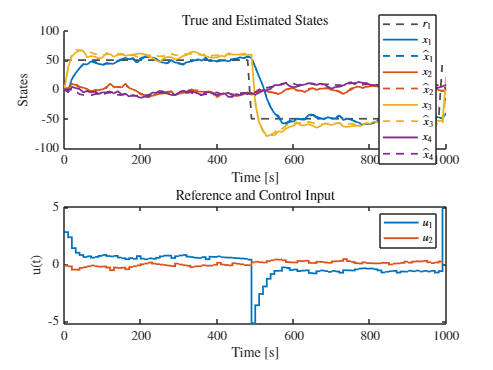

clear
rng(203829)
addpath('functions')
set(groot, 'defaultTextInterpreter', 'latex');
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
plotPos = [100 100 800, 400];


%% --- system definition ---
Ts = 10;    % sample time [s]

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];

B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];

C = [1, 0, 0, 0;
     0, 1, 0, 0];

% cost / noise‐covariance matrices (as given)
Q= [8.0209, 0.2260, 1.5334, 0.0812;
       0.2260, 8.0209, 0.0812, 1.5334;
       1.5334, 0.0812, 7.4082, 0.0172;
       0.0812, 1.5334, 0.0172, 7.4082];
R = eye(2);    % = R2

W = Q;         % assumed process‐noise covariance
V = R;         % assumed measurement‐noise covariance

%% --- LQR controller design ---
[K,~,~] = dlqr(A,B,diag([1,1,0,0]),R*250);
% lambda = eig(A)
% K = place(A,B,lambda*0.85)

%% --- Kalman filter design (steady‐state) ---
%   L is the state‐estimator gain:  xhat+ = A*xhat + B*u + L*(y - C*xhat)
% Solve the discrete Riccati equation
[P,~,~] = dare(A', C', Q, R);
[P,~,~] = idare(A', C', Q, R);

% Compute stationary Kalman gain
Kf = P * C' / (C * P * C' + R);



%% --- simulation setup ---
Tfinal = 1000;            % total simulation time [s]
N = Tfinal / Ts;         % number of steps



T = N; % Periode in sampels
ref1 = 50*square(2*pi*1/T*(1:N),50);
ref2 = zeros(1,N);
ref = [ref1;ref2];
dcG = (C*(eye(4) - (A-B*K))^(-1) * B)^-1;

yhat  = zeros(2, N);     % predicted outputs
x     = zeros(4,   N+1);   % true state
xhat  = zeros(4,   N+1);   % estimated state
u     = zeros(2,   N);
y     = zeros(2,   N);
P    = 1*eye(4);        % init error‐covariance
P_pred    = P;
xhat_pred = xhat(:,1);


rng(0);  % for reproducible noise


for k = 1:N
    % Simulate measurement
    v = mvnrnd(zeros(size(R,1),1), R)';
    y(:,k) = C*x(:,k) + v;

    innov = y(:,k) - C*xhat_pred;
    xhat(:,k) = xhat_pred + Kf*innov;
    yhat(:,k)   = C*xhat(:,k);

    % Controller (if any), could be 0 or feedback
    u(:,k) = -K*xhat(:,k) + dcG * ref(:,k);

    % True system evolution
    w = mvnrnd(zeros(size(Q,1),1), Q)';
    x(:,k+1) = A*x(:,k) + B*u(:,k) + w;

    xhat_pred = A*xhat(:,k) + B*u(:,k);
end

time = 0:Ts:Tfinal;
colors = lines(4);
%% --- plotting ---
figure;
subplot(2,1,1); hold on
plot(time(1:end-1), ref(1,:), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
for i = 1:4
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend({'$r_1$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'}, ...
       'Location','best');
title('True and Estimated States');

subplot(2,1,2); 
stairs(time(1:end-1), u(:,:)', '-',  'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$');
title('Reference and Control Input');